# Fourier Transform

**Learning Goals**

- LG1

- LG2

## Introduction

Complex Fourier series can be used to analyze periodic functions in the frequency domain. Recall the complex Fourier series:


$$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$$


By plotting the magnitude of the Fourier coefficients $c_n$, you can identify which frequencies are dominant.

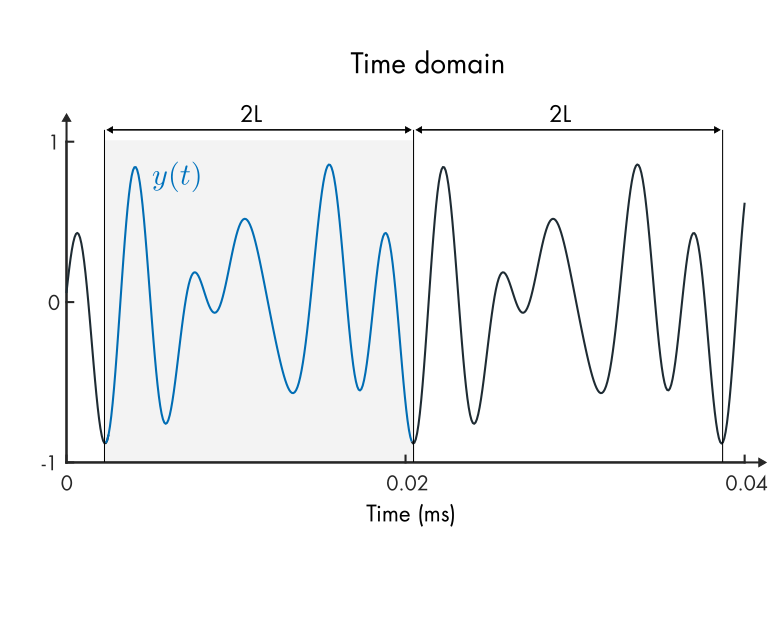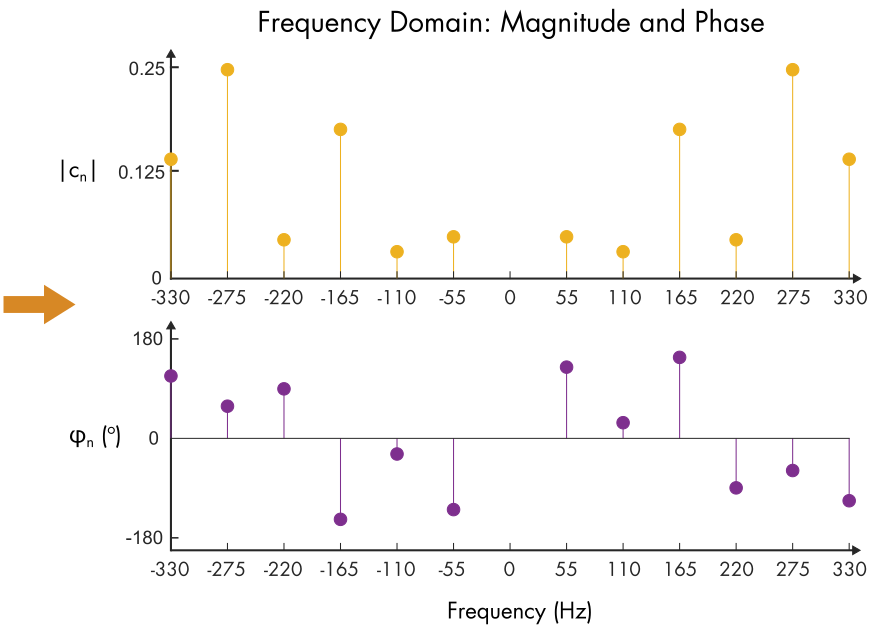

*A simplified guitar chord in the time and frequency domains. First pane: the 2L periodic function in the time domain. Second pane: the magnitude and phase of the coefficients *$c_n$* of the complex Fourier series. Because *$y(t)$ *is real, the coefficients are mirrored at negative frequencies.*

In this chord, we can see that the C# note (275 Hz) is dominant. 

Because the audio signal produced by a guitar is largely periodic, a complex Fourier series provides good estimates for the frequency domain. But how can you compute the frequency domain for a function that is not periodic?

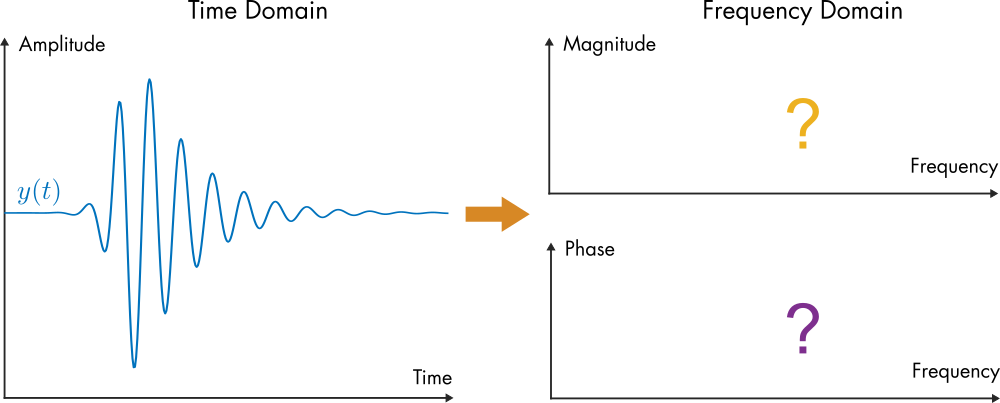

*What will the frequency domain plots of *$y(t)$* look like?*

**Estimating the frequency content of a non-periodic function with Fourier series**

It is possible to assume a finite domain (of length $2L$) that encompasses most of a non-periodic function, and identify the Fourier series coefficients for that domain. This results will indeed provide information about the frequency content of the function. However, it will never provide a true representation of the original function, since by definition the Fourier series will always generate periodic copies ever 2L.

    **Activity. **The plots below illustrate complex Fourier series estimates of a non-periodic function. 

- Adjust `L` to change the size of the domain on which the Fourier series is computed.

- Adjust` N` to change the number of frequencies used in the complex Fourier series.

**Task 1. **Press **Show plot**. Observe the four plots. 

- The plot labeled **Fourier Series Reconstruction** shows the actual function modeled by the Fourier series (as opposed to the original function, $y(t)$, graphed in the first plot).

- The frequency domain plot with y-axis label $\angle c_n$ shows the phase angle in radians. 

**Task 2. **Set `L = 1` and `N = 10`. Is the $y(t)$ captured?

**Task 3.** Set `L = 2` and then `L = 3`. Does this improve the estimate?

**Task 4. **With `L = 3` and `N = 10`, are there enough modes? If not, increase the number of modes `N` until the majority of the frequency content is captured.

**Task 5. **Expand the domain to `L = 5`. Increase the number of modes `N `until the majority of the frequency content is captured.

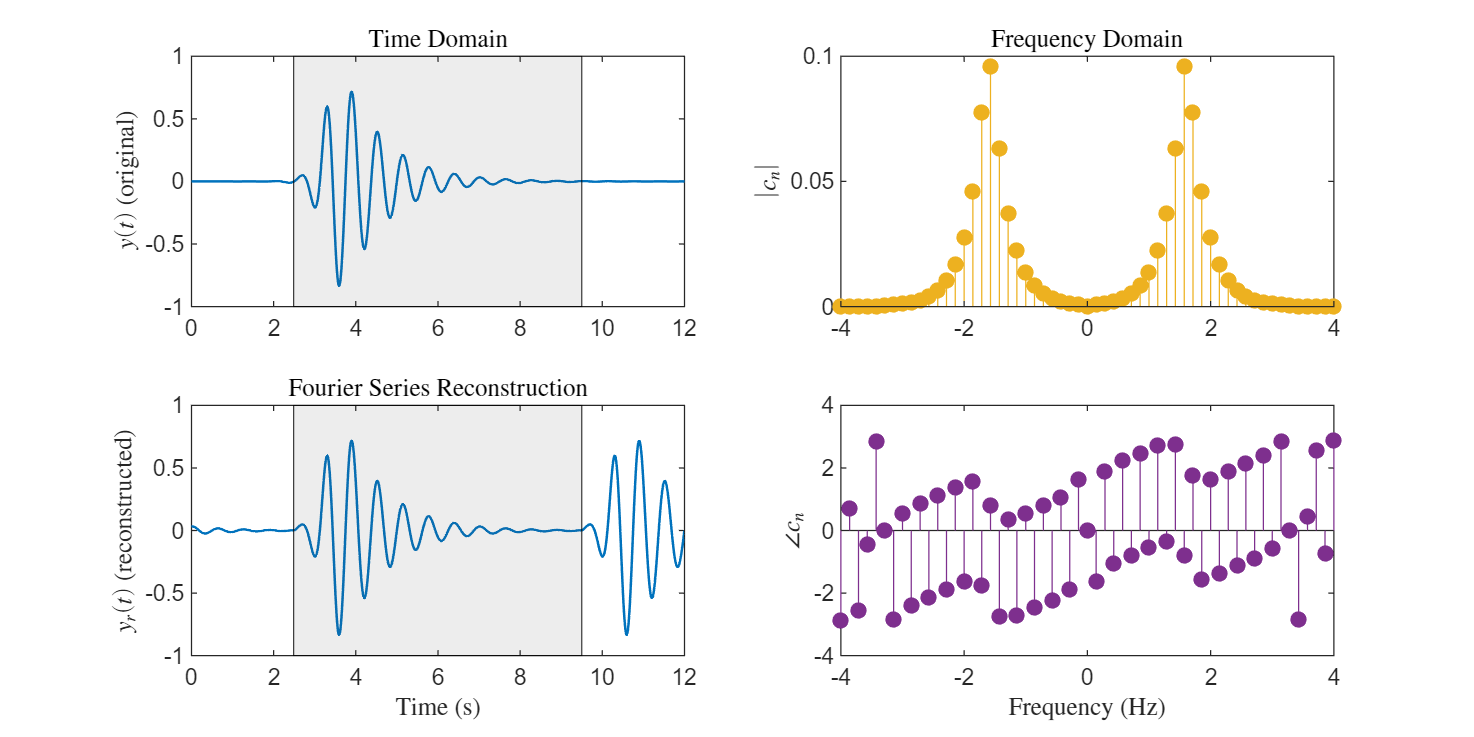

L = 3.5; % The domain half-width
N = 55; % The number of Fourier modes to use in the series
 
fourierEstimateSech(L,N) % Helper function that creates the plots

**  Reflect.** 

- If you want to increase the resolution of the frequency domain (i.e., make the stems closer to each other), should you increase the domain width `L` or the number of frequencies `N`?

- In the case where `L = 5`, no periodic copies of the function are visible in the reconstruction, $y_r$. In this case, do periodic copies exist in $y_r$?

- How large would the domain need to be for there to be no periodic copies?

- In the case where there are no more periodic copies, what will the resolution of the frequency domain be (i.e., how close will the stems be to each other)?

While the complex Fourier series provides a good estimate, it will never be able to perfectly capture a non-periodic function. For this to be possible, the domain on which the Fourier series is computed must become infinitely large ($L \to \infty$), which is not compatible with Fourier series definition.

The Fourier transform, on the other hand, is capable of analytically representing the entire function in the frequency domain.

## Definition

The Fourier transform of a function $f(t)$ is


$$\hat{f}(\omega) = \int_{-\infty}^\infty f(t) e^{-i\omega t} \ dt$$


In this definition, $\omega$ is the angular frequency.  The inverse Fourier transform can be computed using a complementary definition


$$f(t) = \frac{1}{2 \pi} \int_{-\infty}^\infty \hat{f}(\omega) e^{i\omega t} \ dt$$


There are several alternative definitions to the Fourier transform. This definition has been selected because it is used by the symbolic functions for the Fourier transform in MATLAB: [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) and [`ifourier`](https://www.mathworks.com/help/symbolic/sym.ifourier.html). 

Note that not every function has a well-defined Fourier transform. 

 **Example. **A simple Gaussian with a single parameter $a$ is


$$y(t) = e^{- a t^2}$$


Gaussian curves have well defined and (relatively) easy to compute Fourier transform. 


$$\begin{array}{rl}
\hat{y}(\omega) &= \int_{-\infty}^\infty e^{-a t^2} e^{-i\omega t} \ dt
\\
&= \int_{-\infty}^\infty e^{- a( t^2 + i\omega t/a - \omega^2/(4a^2)) - \omega^2/(4a)} \ dt
\\
&= e^{ - \frac{\omega^2}{4 a}} \int_{-\infty}^\infty e^{- a (t+i\omega/(2a))^2} \ dt
\\
&= \sqrt{\frac{\pi}{a}} e^{ - \frac{ \omega^2}{4a}} 
\end{array}$$


You can validate our result by computing the Fourier series using the [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) function from the Symbolic Toolbox.

syms t omega % Define the symbolic variables
syms a positive % Positive constant a
y = exp(-a*t^2) % Define the function

$$y = {\mathrm{e}}^{-a\,t^{2}}$$

yhat = fourier(y,t,omega) % Compute the Fourier transform

$$yhat = \frac{\sqrt{\pi }\,{\mathrm{e}}^{-\frac{\omega^{2}}{4\,a}}}{\sqrt{a}}$$

To plot the generated symbolic functions, you can use `fplot`. Before doing so, you need to substitute a value for $a$.

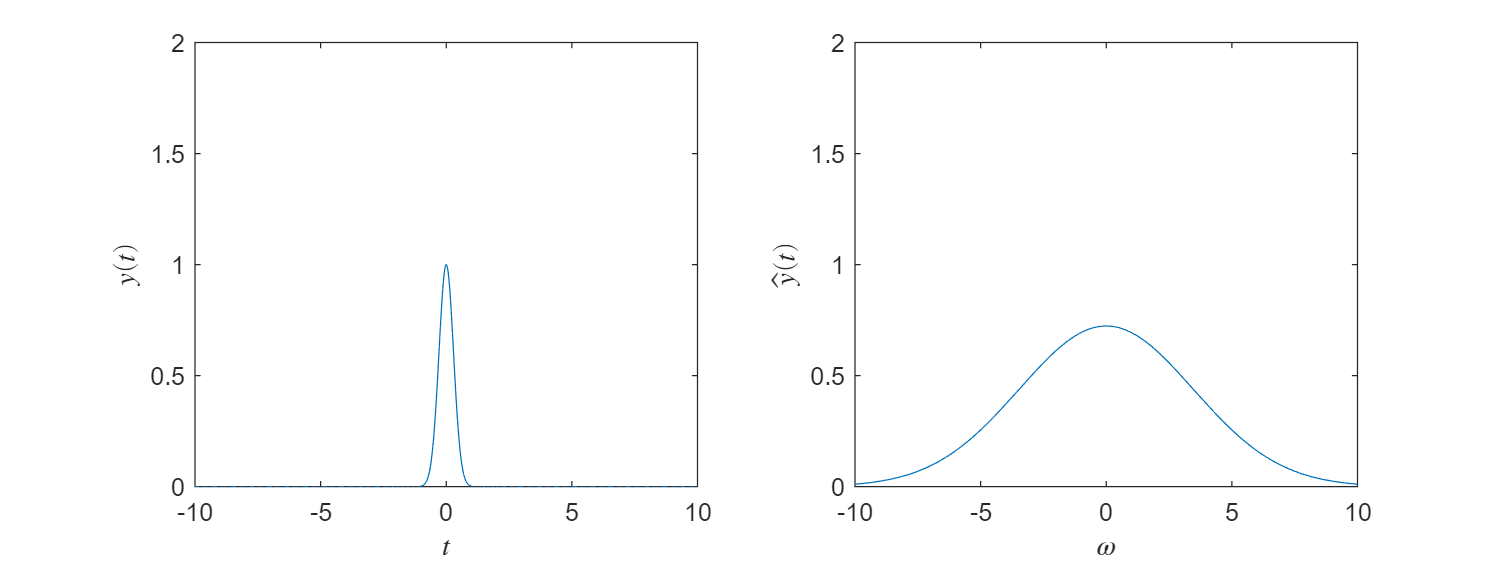

% Substitute a value for a
aValue = 6;
y = subs(y,a,aValue);
yhat = subs(yhat,a,aValue);

% Generate the plot
figure("Position",[1 1 800 300])
subplot(1,2,1)
fplot(t,y,[-10,10])
ylim([0,2])
xlabel("$t$","Interpreter","latex")
ylabel("$y(t)$","Interpreter","latex")
subplot(1,2,2)
fplot(omega,yhat,[-10,10])
ylim([0,2])
xlabel("$\omega$","Interpreter","latex")
ylabel("$\hat{y}(t)$","Interpreter","latex")

function fourierEstimateSech(L,Nmodes)

    % Domain and function
    tf = 12;
    ts = 2;
    tmid = 6;
    sigma = 0.2;
    freq = 1.6;
    
    Nt = 1000;
    ylims = [-1,1];
    tlims = [0,tf];
    freqLims = [-4,4];
    t = linspace(tlims(1),tlims(2),Nt);
    sechValue = 2./(exp((0.2*t-ts)/sigma) + exp(-(t-ts)/sigma));
    y = sin(2*pi*freq*t).*sechValue/1200;

    % Extract the correct interval
    dLims = round( (tmid + [-L,L])*Nt/tf );
    dIdx = dLims(1):dLims(end);
    yc = y(dIdx);
    tc = t(dIdx);

    % Estimate coefficients using trapezoid rule
    nvec = -Nmodes:1:Nmodes;
    freq = nvec/(2*L);
    c = zeros(1,numel(nvec));
    for k = nvec + Nmodes + 1
        c(k) = 1/(2*L)*trapz(tc,exp(-1i*nvec(k)*pi/L*tc).*yc);
    end

    % Compute the Fourier series estimate
    ft = zeros(size(t));
    for k = 1:numel(nvec)
        ft = ft + c(k)*exp(1i*pi/L*nvec(k).*t);
    end


    colors = lines(4);
    figure("OuterPosition",[1,1,800,400])
    subplot(2,2,1)
    plot(t,y,"Linewidth",1)
    patch([tc(1),   tc(1),   tc(end), tc(end),  tc(1)],...
          [ylims(1),ylims(2),ylims(2),ylims(1), ylims(1)],[0.3,0.3,0.3],"FaceAlpha",0.1,EdgeAlpha=0.75)
    ylim(ylims)
    xlim(tlims)
    ylabel("$y(t)$ (original)","Interpreter","latex")
    title("Time Domain","Interpreter","latex")

    subplot(2,2,3)
    plot(t,real(ft),"Linewidth",1)
    patch([tc(1),   tc(1),   tc(end), tc(end),  tc(1)],...
          [ylims(1),ylims(2),ylims(2),ylims(1), ylims(1)],[0.3,0.3,0.3],"FaceAlpha",0.1,EdgeAlpha=0.75)
    xlim(tlims)
    ylim(ylims)
    xlabel("Time (s)","Interpreter","latex")
    ylabel("$y_r(t)$ (reconstructed)","Interpreter","latex")
    title("Fourier Series Reconstruction","Interpreter","latex")

    subplot(2,2,2)
    stem(freq,abs(c),"Filled","Color",colors(3,:))
    xlim(freqLims)
    ylabel("$| c_n |$","Interpreter","latex")
    title("Frequency Domain","Interpreter","latex")

    subplot(2,2,4)
    stem(freq,angle(c),"Filled","Color",colors(4,:))
    xlim(freqLims)
    xlabel("Frequency (Hz)","Interpreter","latex")
    ylabel("$\angle c_n$","Interpreter","latex")

end